This script is to illustrate robot kinematics.

Step 1: Choose a robot

robot = robotproperty("KinovaGen3")

robot = struct with fields:
     name: "KinovaGen3"
    nlink: 6
       DH: [6×4 double]
     base: [3×1 double]


theta = robot.DH(:,1);

Step 2: Choose joint angles (offset in rad)

robot.DH(:, 1) = theta + [
    0.55;
    0.01;
    -0.04;
    0.33;
    -0.07;
    -0.02;
    ];

Step 3: Now let's draw the robot!

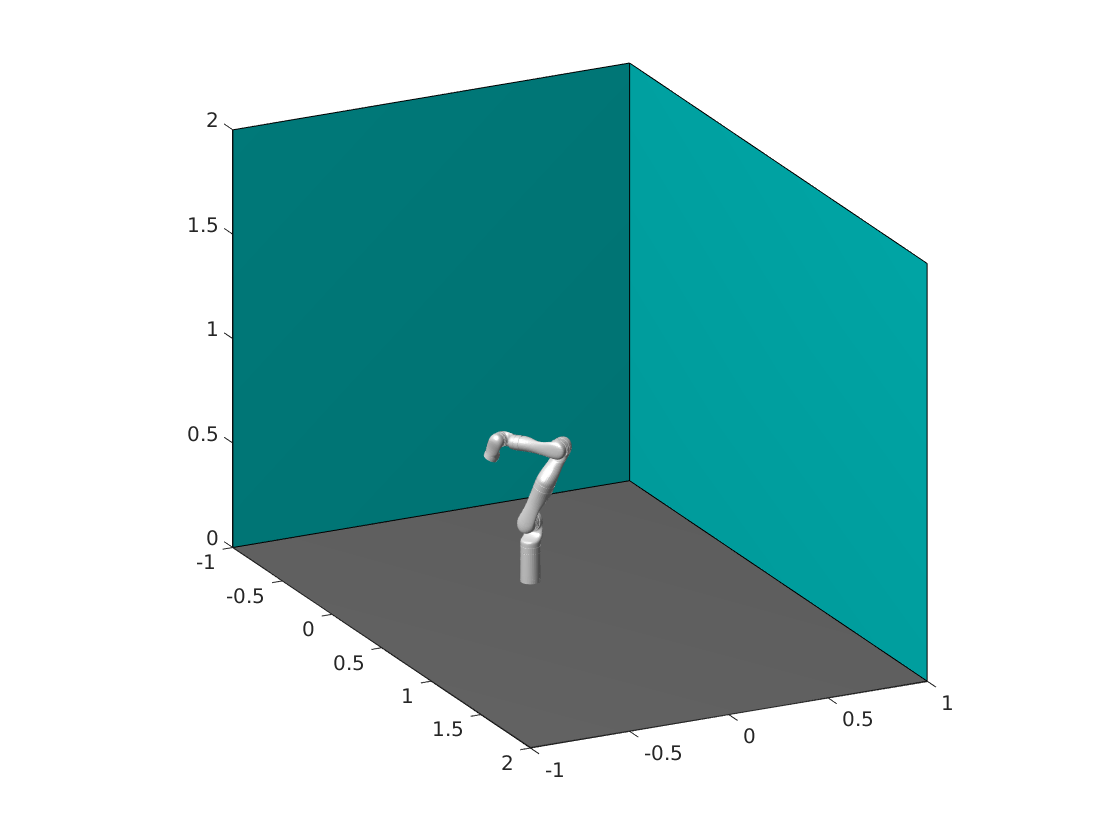

Draw(robot, "CAD");